# Swing by Venus - Numerik Abschlussprojekt

Urs Müller, Joachim Spitaler, Leonie Graf

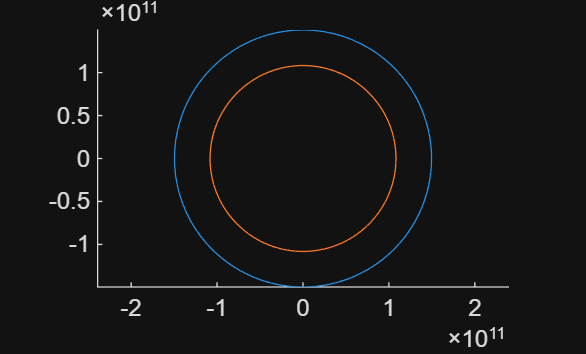

clear all, close all, clc, clf  
r_Mars  = 227990000*10^3;  % Mittlerer Bahnradius Mars 
T_Mars = 686.980; % Tage

tspan = linspace(0,365.25,365.25);

Earth = posEarth(tspan);
Venus = posVenus(tspan);

figure;
hold on;
plot(Earth(:,1), Earth(:,2));
plot(Venus(:,1), Venus(:,2));
axis equal;

Abstand 1% und so

%Startposition der Venus abgreifen
rV = posVenus(0)';
d = linspace(1e5, 1e12, 100000);   % 100 km – 1 Mio km
ratio = zeros(size(d));
for i = 1:length(d)     %Stattdessen mit fzero?
    r_test = rV + [0; d(i)];
    
    y_all = [r_test; 0; 0];
    [~, a_S, a_E, a_V] = grav_calc(0, y_all);
    a_total = a_S + a_E + a_V;
    ratio(i) = norm(a_V) / norm(a_total);
    if ratio(i) <= 0.01
        dist_in_km = d(i) / 1000;
        disp(dist_in_km)
        fprintf("%.2f", ratio(i))
        break
    end
end

     1.700116830168301e+06



0.01

Bahnkurve Sonde, Start tangential zu Erdlaufbahn

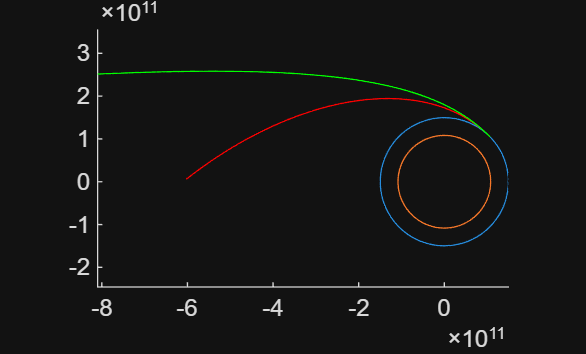

v0 = 15 * 10^3 * 86400; %Startgeschwindigkeit, Meter/Tage
angle = 0;

% Funktion addiert Erdgeschwindigkeit, richtet nach Winkel aus
[pos, v0_vec] = v0_calc(v0, angle);
[t_all, y_all] = ode45(@grav_calc, tspan, [pos'; v0_vec]);
plot(y_all(:,1), y_all(:,2), "r-");

[t_sun, y_sun] = ode45(@grav_sun, tspan, [pos'; v0_vec]);
plot(y_sun(:,1), y_sun(:,2), "g");

Aufgabe, Venus in Abstand von 20000km passieren

v0 = 13.333 * 10^3 * 86400; %Startgeschwindigkeit, Meter/Tage
angles = linspace(1.83, 2.3, 10000);
results = zeros(length(angles), 2); %Vektor für Ergebnisse

options = odeset('AbsTol',1e-10, 'RelTol',1e-10, 'Events', @(t,y) swinger(t,y));

hit = false(length(angles),1);

for j = 1:length(angles)

    [pos, v0_vec] = v0_calc(v0, angles(j));
    y0 = [pos(:); v0_vec(:)];

    [t_all, y_all, te, ye, ie] = ode45(@grav_calc, tspan, y0, options);

    if ~isempty(te)
        hit(j) = true;
    end
end
best_angles = angles(hit);

function [val, term, dir] = swinger(t, y)
    target = 20000 * 10^3;  %Zieldistanz in Metern

    rS = y(1:2)';           %Als Zeilenvektor speichern
    rV = posVenus(t);
    dist = norm(rV - rS);

    val = target - dist;                  %Toleranz, ode45 löst System nur an bestimmten Zeitschritten
    term = 1;                             %Stoppen
    dir = -1;
end